This is a test gas dispersion model using CA automata

The main control equation is: 


$$\displaystyle  \frac{\partial C}{\partial t}=\frac{\partial}{\partial x}\left(K_x\frac{\partial C}{\partial x}\right)+\frac{\partial}{\partial y}\left(K_y\frac{\partial C}{\partial y}\right)+\frac{\partial}{\partial z}\left(K_z\frac{\partial C}{\partial z}\right)-U_x\frac{\partial C}{\partial y} -U_y\frac{\partial C}{\partial y}-\lambda C \pm \delta C$$


 Mean concentration C is a function: $C(x,y,z,t)$. When assigned with cells in the modeling domain, $^{t+1}C_{ijk}$is the mean concentration of released substance at cell $(i,j,k)$. 


$$^{t+1}C_{ijk}=f\left(^tC_{ijk},\Delta^tC^{ad}_{1-8},\Delta^tC^{tur}_{9-10},^t\delta_{ijk},^t\lambda_{ijk}\right)$$


The adjacent influence on current center cells could be limited by coefficient $w$, which:


$$w_{i,j,k-1}=w_{i-1,j,k}=w_{i+1,j,k}=w_{i,j+1,k}=w_{i,j-1,k}=w_a$$


For non-adjacent coefficient: 


$$w_{i+1,j-1,k}=w_{i-1,j-1,k}=w_{i+1,j+1,k}=w_{i-1,j+1,k}=w_b$$


which indicates the isotropy of neighbor impacts.

Then we get:


$$^{t+1}C_{ijk}  =^tC_{ijk}+w_a[^tu_s(C_{i,j-1,k}-C_{i,j,k})+^tu_n(C_{i,j+1,k}-C_{i,j,k}) \\
~~~~~~~~ + ^tu_e(C_{i+1,j,k}-C_{i,j,k})+^tu_w(C_{i-1,j,k}-C_{i,j,k}) ]\cdot \Delta t \\
~~~~~~~~+w_b[^tu_{se}(C_{i+1,j-1,k}-C_{i,j,k}) + ^tu_{nw}(C_{i-1,j-1,k}-C_{i,j,k}) \\
~~~~~~~~+^tu_{ne}(C_{i+1,j+1,k}-C_{i, j,k})+^tu_{sw}(C_{i-1,j+1,k}-C_{i,j,k})]\\
~~~~~~~~+w_a[k^'_z(C_{i,j,k-1}-C_{i,j,k})+k^"_z(C_{i,j,k+1}-C_{i,j,k})] \\
~~~~~~~~-^t\delta_{ijk}^tC_{ijk}-^t\lambda_{ijk}^tC_{ijk}$$


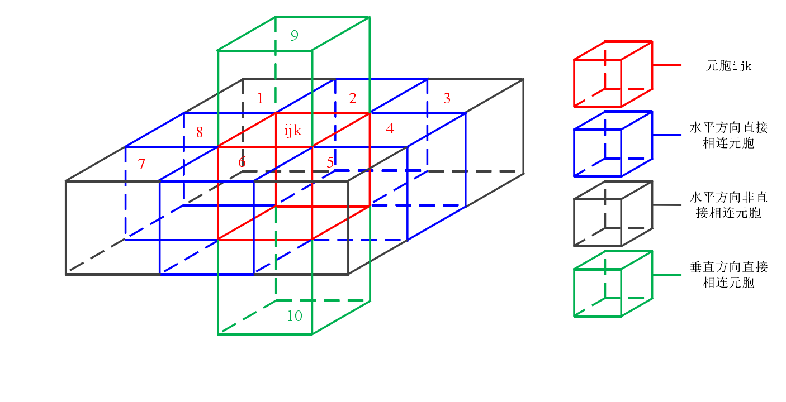

Section 2: Cellular model implementation

Variable definations:     $\text{wc(2)}=[w_a, w_b] \\
\text{wd(8)}=[w_n, w_s, w_e, w_w, w_{ne}, w_{nw}, w_{se}, w_{sw}]$